# Part-III 1200bit数据传输任务

clear all, close all, clc

## (使用已测出并存储的数据直接绘图)

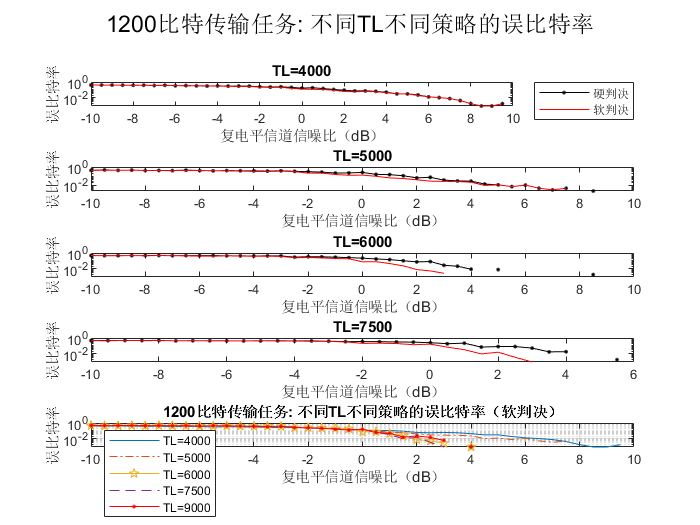

snr_dB = load("Data\transtask_1200bits.mat").snr_dB;
BER = load("Data\transtask_1200bits.mat").BER;
%%
subplot(5,1,1);
semilogy(snr_dB,BER(1,:), 'k.-', snr_dB,BER(2,:), 'r-');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('TL=4000');
legend('硬判决', '软判决', 'Location', 'eastoutside');
subplot(5,1,2);
semilogy(snr_dB,BER(3,:), 'k.-', snr_dB,BER(4,:), 'r-');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('TL=5000');
subplot(5,1,3);
semilogy(snr_dB,BER(5,:), 'k.-', snr_dB,BER(6,:), 'r-');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('TL=6000');
subplot(5,1,4);
semilogy(snr_dB,BER(7,:), 'k.-', snr_dB,BER(8,:), 'r-');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('TL=7500');
subplot(5,1,5);
semilogy(snr_dB,BER(9,:), 'k.-', snr_dB,BER(10,:), 'r-');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('TL=9000');
sgtitle('1200比特传输任务: 不同TL不同策略的误比特率')
%%
semilogy(snr_dB,BER(1,:), '-', ...
    snr_dB,BER(3,:), 'k:', ...
    snr_dB,BER(5,:), 'r-p', ...
    snr_dB,BER(7,:), '-o', ...
    snr_dB,BER(9,:), '-.');
legend('TL=4000','TL=5000','TL=6000','TL=7500','TL=9000',  'Location', 'southwest');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('1200比特传输任务: 不同TL不同策略的误比特率（硬判决）')
grid
% 软判决
hold off
semilogy(snr_dB,BER(2,:), '-', ...
    snr_dB,BER(4,:), '-.', ...
    snr_dB,BER(6,:), '-p', ...
    snr_dB,BER(8,:), '--', ...
    snr_dB,BER(10,:), 'r.-');
legend('TL=4000','TL=5000','TL=6000','TL=7500','TL=9000',  'Location', 'southwest');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('1200比特传输任务: 不同TL不同策略的误比特率（软判决）')
grid

# 完整模块

## 数据生成与参数确定

clear all, close all, clc

% 传输数据
N = 1200;               % 数据量
x = randi(2, 1, N)-1;   % 传输数据
% 映射系数的调控
T=5;
mbit = 2;
snr_low = -10;          % snr最低值(dB)
snr_high = 10;          % snr最高值(dB)
snr_step = 0.5;         % snr步长
% 卷积矩阵
A_2 = [1 1 0 1          % 1/2效率
     1 1 1 1]';
% 映射矩阵
Mmap2 = [ -1 -1;    -1  1;    1 -1;    1  1 ];

## 编码 映射 信道传输 译码

TL=4000，5000，6000，7500，9000时采用不同策略进行传输

hxx, sxx分别代表TL=xx00时使用硬/软判决方法译码得到的数据

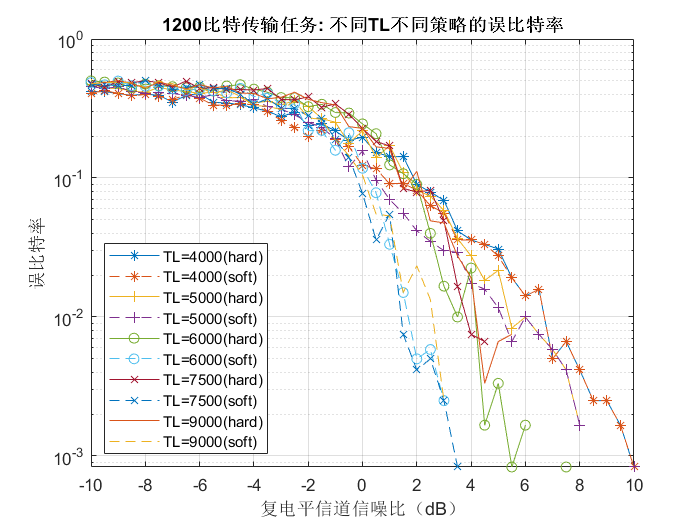

% 不添加CRC
crc_code = x;

% 映射前的过程与snr无关
snr_dB = snr_low:snr_step:snr_high;     % SNR取值集
BER = repmat(snr_dB*0, [4 1]);          % 误码率记录矩阵: 编码策略数 × SNR取值数

% TL=4000, 5000, 6000: 前...个不编码 后面部分使用1/2效率不收尾卷积编码 均采用2-bit映射
[h40BER s40BER] = task01(4000, crc_code, 800, snr_dB);
[h50BER s50BER] = task01(5000, crc_code, 400, snr_dB);
[h60BER s60BER] = task01(6000, crc_code, 0, snr_dB);
BER = repmat([h40BER;s40BER; h50BER;s50BER; h60BER;s60BER; BER], [1 1]);

for i=1:length(snr_dB)
    % 映射参数按照snr与mbit进行配置
    snr = 10^(snr_dB(i)/10);
    Mmap = sqrt(snr/2)*Mmap2;
    
    % TL=7500, L=1500: 全部使用1/2效率收尾卷积编码及2-bit映射
    L = 7500/5;
    tl75_c2n_m2 = mapping(conv_encode(crc_code, A_2, 1), 0, 2, Mmap);
    u75 = tl75_c2n_m2;
    v75 = channel(u75, T, size(u75, 2));
    bit75 = mapping(v75, 1, 2, Mmap);
    s75 = viterbi(v75, A_2, 1, "soft", Mmap);
    h75 = viterbi(bit75, A_2, 1, "hard", Mmap);
    % TL=9000, L=1800: 全部使用1/2效率收尾卷积编码及2-bit映射
    L = 9000/5;
    tl90_c2n_m2 = mapping(conv_encode(crc_code, A_2, 1), 0, 2, Mmap);
    u90 = tl90_c2n_m2;
    v90 = channel(u90, T, size(u90, 2));
    bit90 = mapping(v90, 1, 2, Mmap);
    s90 = viterbi(v90, A_2, 1, "soft", Mmap);
    h90 = viterbi(bit90, A_2, 1, "hard", Mmap);
    BER(7,i)=sum(abs(h75-crc_code))/N;%crc_code
    BER(8,i)=sum(abs(s75-crc_code))/N;
    BER(9,i)=sum(abs(h90-crc_code))/N;
    BER(10,i)=sum(abs(s90-crc_code))/N;
end

%save("Data\transtask_1200bits_new.mat", "BER", "snr_dB");

semilogy(snr_dB,BER(1,:), '-*', snr_dB,BER(2,:), '--*', ...
    snr_dB,BER(3,:), '-+', snr_dB,BER(4,:), '--+', ...
    snr_dB,BER(5,:), '-o', snr_dB,BER(6,:), '--o', ...
    snr_dB,BER(7,:), '-x', snr_dB,BER(8,:), '--x', ...
    snr_dB,BER(9,:), '-', snr_dB,BER(10,:), '--');
legend('TL=4000(hard)','TL=4000(soft)',  'TL=5000(hard)','TL=5000(soft)',  'TL=6000(hard)','TL=6000(soft)',  'TL=7500(hard)','TL=7500(soft)',  'TL=9000(hard)','TL=9000(soft)',  'Location', 'southwest');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('1200比特传输任务: 不同TL不同策略的误比特率')
grid